# Lab 5 - Zakary Steenhoek - MAT 275 Lab 5

The Mass-Spring System

# Exercise 1

### Part (a)

The curve that represents y=y(t) is the red curve. I know because, when the red curve is at its max/min amplitude and has a slope of 0, the blue graph has a value of 0. In other words, the blue graph is one quarter phase behind the red graph, and therefore the leading (red) graph must be the origional function while the lagging (blue) graph must be the derivitive of said function.

### Part (b)

For the red graph, visually the period is roughly 1.6 units. If we solve for T using T=2(pi)/(omega), with omega = sqrt(k/m), we get T = pi/4 = 1.57017963.

### Part (c)

This mass will never come to rest because there is no damping force to take any energy out of the system. Therefore, the system is an example of undamped simple harmonic motion and will oscillate indefinitely.

### Part (d)

The amplitude of the oscillations for y(t), or the red graph, is roughly 0.9 units.

### Part (e)

The maximum velocity attained by the mass can be found using the blue graph - the graph of v(t), or the derivitive of the graph of y(t). The maximum value of this graph is the abs(amplitude), which is roughly 3.6 units. This value is attained at the time values 

t = (0.404199, 1.1817, 1.98784, 2.73059, 3.51922, 3.59388)

### Part (f)

type LAB05ex1_1.m

clear all;     % clear all variables 
m = 8;  % mass [kg]
k = 16;  % spring constant [N/m]
omega0 = sqrt(k/m); 
y0 =0.9;  v0 = 0; % initial conditions
[t,Y] = ode45(@f,[0,5],[y0,v0],[],omega0); % solve for 0<t<5
y = Y(:,1); v = Y(:,2);  % retrieve y, v from Y 
figure(1); clf; plot(t,y,'ro-',t,v,'b+-'); % time series for y and v
legend('y(t)', 'v(t)'); title('Ex. 1: y(t) and v(t) for m=8, k=16'); xlabel('Time (t), measured in seconds');
grid on; axis tight; 
%---------------------------------------------------
function dYdt = f(t,Y,omega0); % function defining the DE 
y = Y(1); v = Y(2); 
dYdt=[ v ; - omega0^2*y ];
end


LAB05ex1_1
type LAB05ex1_2.m

clear all;     % clear all variables 
m = 1;  % mass [kg]
k = 36;  % spring constant [N/m]
omega0 = sqrt(k/m); 
y0 =0.9;  v0 = 0; % initial conditions
[t,Y] = ode45(@f,[0,5],[y0,v0],[],omega0); % solve for 0<t<5
y = Y(:,1); v = Y(:,2);  % retrieve y, v from Y 
figure(2); clf; plot(t,y,'ro-',t,v,'b+-'); % time series for y and v
legend('y(t)', 'v(t)'); title('Ex. 2: y(t) and v(t) for m=1, k=36'); xlabel('Time (t), measured in seconds');
grid on; axis tight; 
%---------------------------------------------------
function dYdt = f(t,Y,omega0); % function defining the DE 
y = Y(1); v = Y(2); 
dYdt=[ v ; - omega0^2*y ];
end


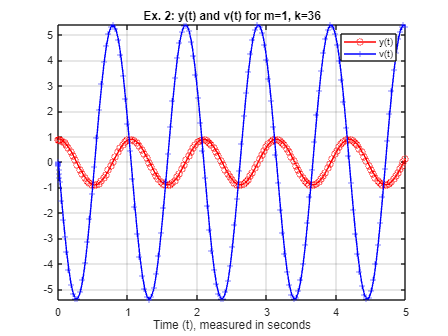

LAB05ex1_2

Comment: As seen in the graphs above, the only factors that can affect the period of motion are the size of the mass *m* and the stiffness of the spring constant, *k, b*ecause the period is T = 2(pi)/w0, and w0 = sqrt(k/m). Therefore we can determine the relationship between the period and the values of k &m as T=2(pi)/sqrt(k/m). From this equation, is is clear that the period is larger and closer to the value of 2*pi when the value of w0 is smaller. The value of w0 is minimized when the value of k/m is smallest, meaning the period is maximized when the value of m is larger and the value of k is smaller. The inverse also holds true, where the period is minimized when the mass is small and the spring constant is large.

# Exercise 2

### Part (a)

type LAB05ex2_1.m

clear all; % clear all variables
m = 1; % mass [kg]
k = 16; % spring constant [N/m]
omega0 = sqrt(k/m);
y0 =0.9;  v0 = 0; % initial conditions
[t,Y] = ode45(@f,[0, 5],[y0,v0],[],omega0); % solve for 0<t<5
y = Y(:,1); v = Y(:,2); % retrieve y, v from Y 
E = (0.5*m*v.^2) + (0.5*k*y.^2); % Equation for total energy of the system
figure(3); clf; plot(t,y,'ro-',t,E,'gx-'); % time series for y and E
legend('y(t)', 'E(t)'); title('Position Plot and Total Energy plot for m=1, k=16'); xlabel('Time (t), measured in seconds');
grid on; axis tight;
%---------------------------------------------------
function dYdt = f(t,Y,omega0); % function defining the DE 
y = Y(1); v = Y(2); 
dYdt=[ v ; - omega0^2*y ];
end


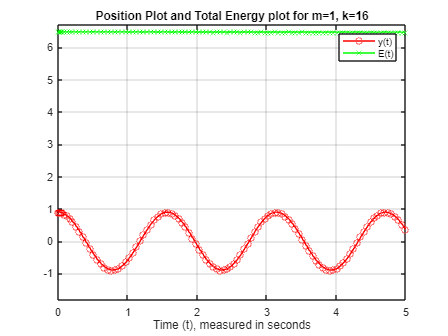

LAB05ex2_1
ylim([-1.8 6.7])

Comment: From the graph, we can see that the value of E(t) is a constant straight line at roughly y=6.5. This means that the combination of kinetic and spring potential energy always equals the same value, 6.5, and never decreases, showing that the energy of the system is conserved. 

### Part (b)

Main Steps:

- **First, differentiate **$E\left(t\right)$** with respect to **$t$** using the chain rule.**

- E(t) = 0 = (0.5*m*v^2) + (0.5*k*y^2); *dE/dt = (2*0.5)(m*v)(dv/dt) + (2*0.5)(k*y)(dy/dt); 1*(m*v)(dv/dt) = -1*(k*y)(dy/dt)*

- **Next, make substitutions using the expression for **$\omega_0$** and using the differential equation.**

- m*v*(dv/dt) = v*-k*y; dy/dt = v

- (-ky)v = -(ky)v; dE/dt = 0

### Part (c)

type LAB05ex2_2.m

clear all; % clear all variables
m = 1; % mass [kg]
k = 16; % spring constant [N/m]
omega0 = sqrt(k/m);
y0 =0.9;  v0 = 0; % initial conditions
[t,Y] = ode45(@f,[0, 5],[y0,v0],[],omega0); % solve for 0<t<5
y = Y(:,1); v = Y(:,2);         % retrieve y, v from Y 
figure(4); clf; plot(y,v,'ro-'); % Phase plot v vs. y
legend('Phase Plot'); title('Phase plot of v vs. y for m=1, k=16'); xlabel('y(t)'); ylabel('v(t)');
grid on; axis tight;
%---------------------------------------------------
function dYdt = f(t,Y,omega0); % function defining the DE 
y = Y(1); v = Y(2); 
dYdt=[v; -omega0^2*y];
end


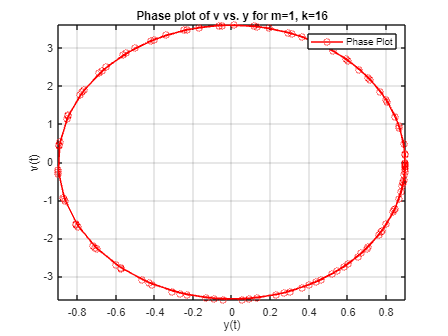

LAB05ex2_2

Comment: From the graph, we can clearly see that the phase plot does not come near the origin (0,0), it instead follows an eliptical path around it. This is because there is no damping and energy is conserved, so the phase plot will go around in this elipse shape indefinitely. The only possible way for the phase graph to come near or cross through the origin is if y(t) and v(t) are close to or equal to 0 at the same time, which can only happen if the system is moving very slightly or no longer moving. Since the system is moving without a damping force, no energy will be lost and the system will be oscillating indefinitley, so there will never be a point where both the value of y(t) and v(t) is equal to zero.

# Exercise 3

### Part (a)

modify the system of equations in LAB05ex3_1 write the t value. If you use the given matlab commands you will need to explain them. 

type LAB05ex3_1.m

clear all;     % clear all variables 
m = 1;  % mass [kg]
k = 16;  % spring constant [N/m]
c = 2;  % friction coefficient [Ns/m]
omega0 = sqrt(k/m); p = c/(2*m); 
y0 =0.9;  v0 = 0; % initial conditions
[t,Y] = ode45(@f,[0,5],[y0,v0],[],omega0, p); % solve for 0<t<5
y = Y(:,1); v = Y(:,2); % retrieve y, v from Y 
figure(5); clf; plot(t,y,'ro-',t,v,'b+-');% time series for y and v 
legend('y(t)', 'v(t)'); title('Ex. 3: y(t) and v(t) for m=1, c=2, k=16'); xlabel('Time (t), measured in seconds');
grid on; axis tight; 
%---------------------------------------------------
function dYdt = f(t,Y,omega0,p); % function defining the DE 
y = Y(1); v = Y(2); 
dYdt=[v; -2*p*v - omega0^2*y];
end


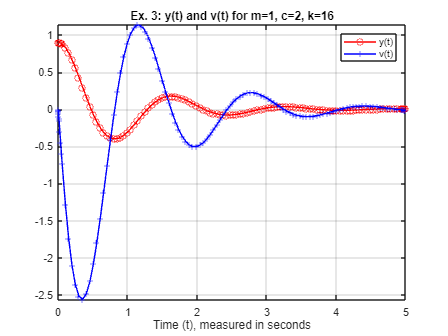

LAB05ex3_1

for i=1:length(y)
    M(i) = max(abs(y(i:end)));
end
i = find(M<0.06); i = i(1);
disp(['|y| < 0.06 for t > t1 with ' num2str(t(i-1)) '< t1 <' num2str(t(i))]);

|y| < 0.06 for t > t1 with 2.617< t1 <2.6674


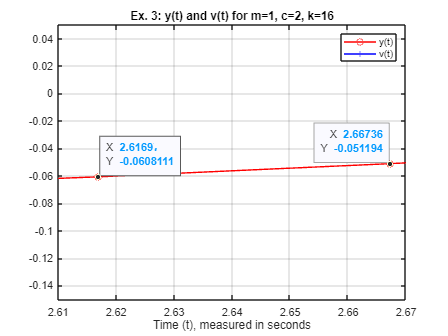

LAB05ex3_1

xlim([2.61 2.67]); ylim([-0.15 0.05]);
ax2 = gca;
chart2 = ax2.Children(2);
datatip(chart2,2.667,-0.05119); datatip(chart2,2.617,-0.06081);

Explanation: The MATLAB commands above are used to find the minimal time *t1* that the mass-spring system satisfies |y(t)| < 0.06 for all t > t1, or in other words, where the positive or negative value of y(t) at time t falls below a magnitude of 0.06. First, a 'for' loop is used to create vector M, containing the maximum magnitude of values in different subvectors of y, with these subvectors being from the value i of the 'for' loop itieration to the end of the vector y. The length of vector y is used as the number of itierations for this loop, and therefore Vector M is the same length as vector y. In other words, it finds the *maximum value* of the *absolute values* of y, between the indexes of the iteration number and the end of the vector. This vector is then passed as an argument into *find*, which searches for and returns every index of vector M where its value falls below the value 0.06, and finally variable 'i' is ultimately defined as the index of the first occurance of this. Finally, the answer to the question "For what minimal time t1 will the mass-spring system satisfy |y(t)| < 0.06 for all t > t1?" is displayed using disp() and the values we calculated. This answer is  checked and confirmed correct in the second, zoomed display of the graph of example 3_1. In this graph, it can be seen that the first time the graph of y(t) has an abs(amplitude) less than 0.06 is between the time values we calculated.

### Part (b)

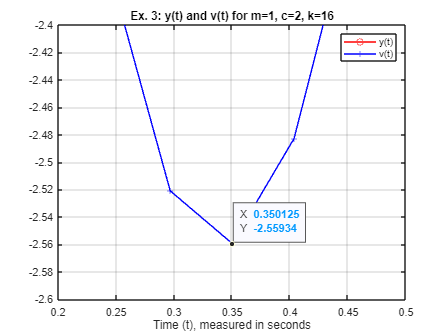

LAB05ex3_1;

xlim([0.2 0.5]); ylim([-2.6 -2.4]);
ax = gca;
chart = ax.Children(1);
datatip(chart,0.3501,-2.559);

The largest velocity attained by the mass is on its first oscillation to negative max amplitude. Here, the mass attains a negative magnitude of velocity of v = 2.55934 m/s at time t = 0.350125.

### Part (c)

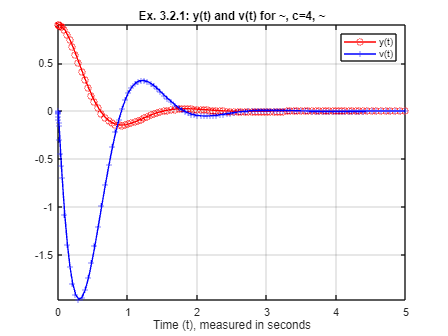

LAB05ex3_2_1

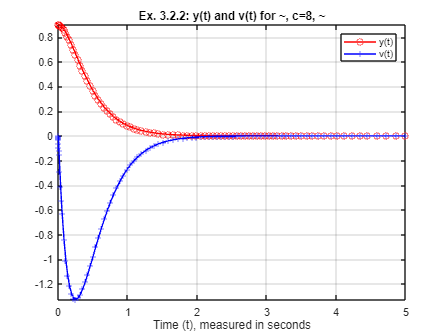

LAB05ex3_2_2

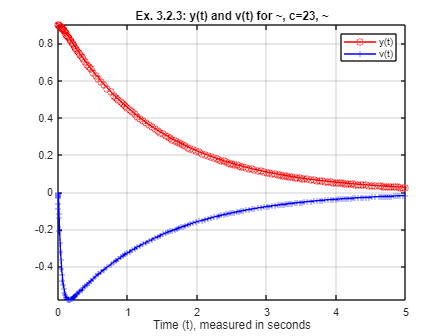

LAB05ex3_2_3

### Part (d)

A spring-mass system is defined as critically damped when the system exhibits no oscillation, and it occurs when the discriminant of the characteristic equation is equal to zero. The value of damping required to achieve this solution can be found by solving 0 = c^2 - 4*m*k. Plugging our values m=1 and k=16 into this equation and setting it equal to 0, we can solve for the value of c that makes this system critically damped. 

Main Steps: 

- **First, write differential equation for motion with known values and set equal to zero (for critically damped motion).**

- y(t) = (1 * d^2y/dt^2) + (c * dy/dt) + (16 * y) = 0

- **Next, write characteristic equation for this system, set discriminant equal to 0, and solve for c.**

- 16 * r^2 + c * r + k = 0; c^2-4(16)(1) = 0 ---> c = sqrt(64)

- c = 8

These steps lead us to calculate that the smallest critial damping coefficient for this system is c = 8. With this damping value, the system will not oscillate whatsoever.

# Exercise 4

### Part (a)

type LAB05ex4_1.m

clear all;     % clear all variables 
m = 1;  % mass [kg]
k = 16;  % spring constant [N/m]
c = 8;  % friction coefficient [Ns/m]
omega0 = sqrt(k/m); p = c/(2*m);
y0 =0.9;  v0 = 0; % initial conditions
[t,Y] = ode45(@f,[0, 5],[y0,v0],[],omega0, p); % solve for 0<t<5
y = Y(:,1); v = Y(:,2); % retrieve y, v from Y 
E = (0.5*m*v.^2) + (0.5*k*y.^2); % Equation for total energy of the system
figure(9); clf; plot(t,y,'ro-',t,E,'gx-'); % time series for y and E
legend('y(t)', 'E(t)'); title('Position Plot and Total Energy plot for m=1, c=2, k=16'); xlabel('Time (t), measured in seconds');
grid on; axis tight;
%---------------------------------------------------
function dYdt = f(t,Y,omega0, p); % function defining the DE 
y = Y(1); v = Y(2); 
dYdt=[v; -2*p*v - omega0^2*y];
end


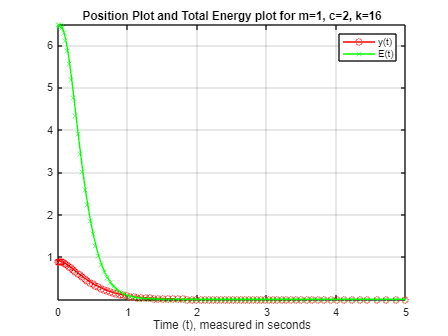

LAB05ex4_1

comment: From the graph, we can clearly see that the value of E(t) is NOT a constant straight line, unlike the E(t) graph in exercise 2, and instead has a downward trend. This means that the combination of kinetic and spring potential energy is decreasing over time, showing that the total energy for this damped spring-mass system is NOT conserved.

### Part (b)

Again, find $\displaystyle \frac{dE}{dt}$ using the chain rule and make substitutions based on the differential equation. You should reach an expression for $\displaystyle \frac{dE}{dt}$ which is in terms of $y^{\prime}$

Main Steps:

- **First, differentiate **$E\left(t\right)$** with respect to **$t$** using the chain rule.**

- E(t) = 0 = (0.5*m*v^2) + (0.5*k*y^2); *dE/dt = (2*0.5)(m*v)(dv/dt) + (2*0.5)(k*y)(dy/dt); dE/dt = 1*(m*v)(dv/dt) + 1*(k*y)*v)*

- **Next, make substitutions using the equation for damped motion and the differential equation**

- (m*(dv/dt)) + (c*v) + k*y = 0 ---> m*(dv/dt) = -c*v - k*y; dE/dt = m*v*(-c*v - k*y) + (k*y*v)

- **Finally, test values for c (c= +- 1)**

- **At c=1, we can see that dE/dt < 0. At c=-1, we can see that dE/dt > 0**

### Part (c)

type LAB05ex4_2.m

clear all;     % clear all variables 
m = 1;  % mass [kg]
k = 16;  % spring constant [N/m]
c = 2;  % friction coefficient [Ns/m]
omega0 = sqrt(k/m); p = c/(2*m);
y0 =0.9;  v0 = 0; % initial conditions
[t,Y] = ode45(@f,[0, 5],[y0,v0],[],omega0, p); % solve for 0<t<5
y = Y(:,1); v = Y(:,2); % retrieve y, v from Y 
E = (0.5*m*v.^2) + (0.5*k*y.^2); % Equation for total energy of the system
figure(10); clf; plot(y,v,'ro-'); % Phase plot v vs. y
legend('Phase Plot'); title('Phase plot of v vs. y for m=1, c=2, k=16'); xlabel('y(t)'); ylabel('v(t)');
grid on; axis tight;
%---------------------------------------------------
function dYdt = f(t,Y,omega0, p); % function defining the DE 
y = Y(1); v = Y(2); 
dYdt=[v; -2*p*v - omega0^2*y];
end


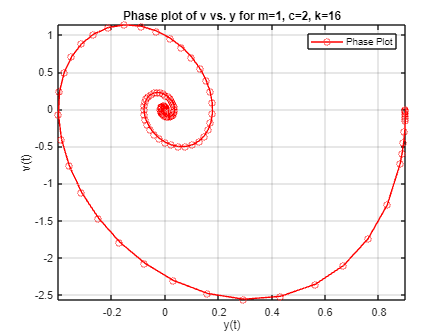

LAB05ex4_2

Comment: From the graph, we can clearly see that the phase plot does come near the origin (0,0), in fact the graph nearly terminates at this location. This is because there is a damping force that sucks energy from the system and energy is not conserved, so the phase plot will draw the demonstrated spiral pattern as energy is leeched until there is no energy left in the system and the system settles into rest with both a position and velocity of 0. If the mass were critically damped, the phase plot would show less than one complete spiral, but it would still terminate at the origin.